# Assignment 3

Name: Ekansh Somani

Roll: 20110065

Course: ES244 - Signals, Systems and Random Processes

## Q1

My Understanding of the question:

- Ultrasound Transducer - Converts electrical energy to mechanical waves.

- Impulse response measured using hydrophone

- Basically we apply voltage to the transducer. It creates mechanical waves using that inside water. The hydrophone detects those waves and converts them to voltage.

- So we have input and output both as voltage in the system. The gain from water is assumed to be 1. While the gain from hydrophone is assumed constant.

Now, at the end of it, we have a received signal in voltage form. And we have to plot its magnitude and phase spectrum.

data = readmatrix("hydrophone.csv");
v = data(:, 5);
t = data(:, 10);

% Now we have two possible approaches.

% t at first glance seems uniformly spaced. Assuming that:

ts = mean(diff(t));
fs = 1 / ts;

n = length(v);
V = fft(v);
f = (0:n-1)*(fs/n);

% Plot only the first half of the spectrum 
f = f(1:n/2+1); % First half of the frequency vector 
V = V(1:n/2+1); % First half of the Fourier Transform

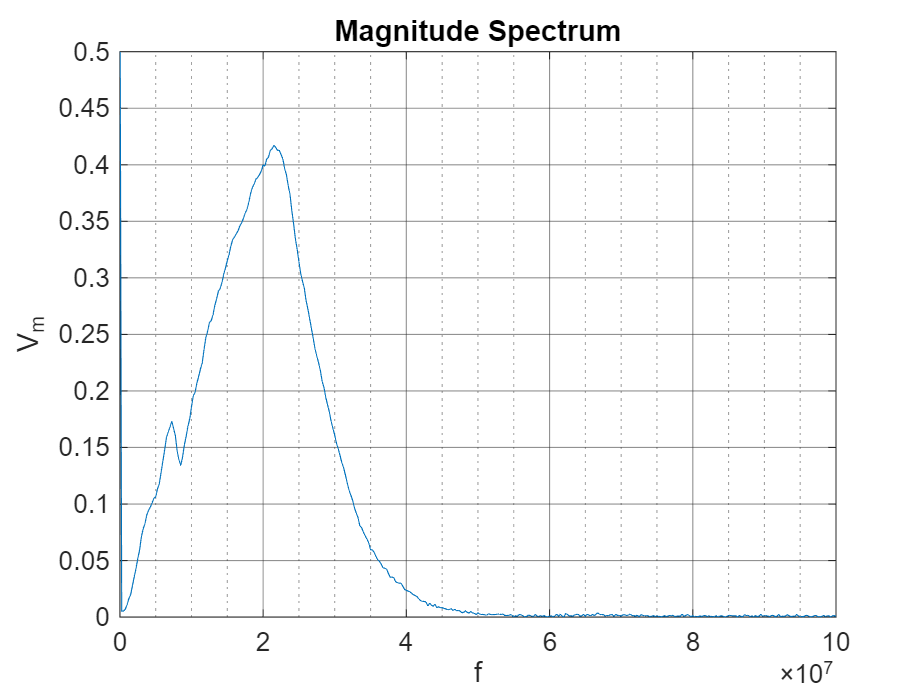

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(f, abs(V));
title('Magnitude Spectrum');
xlim([0,1e8]);
ylim([0, 0.5]);   % optional to resize axis limits
xlabel('f');
ylabel('V_m');

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');

% Set the remaining axes properties
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

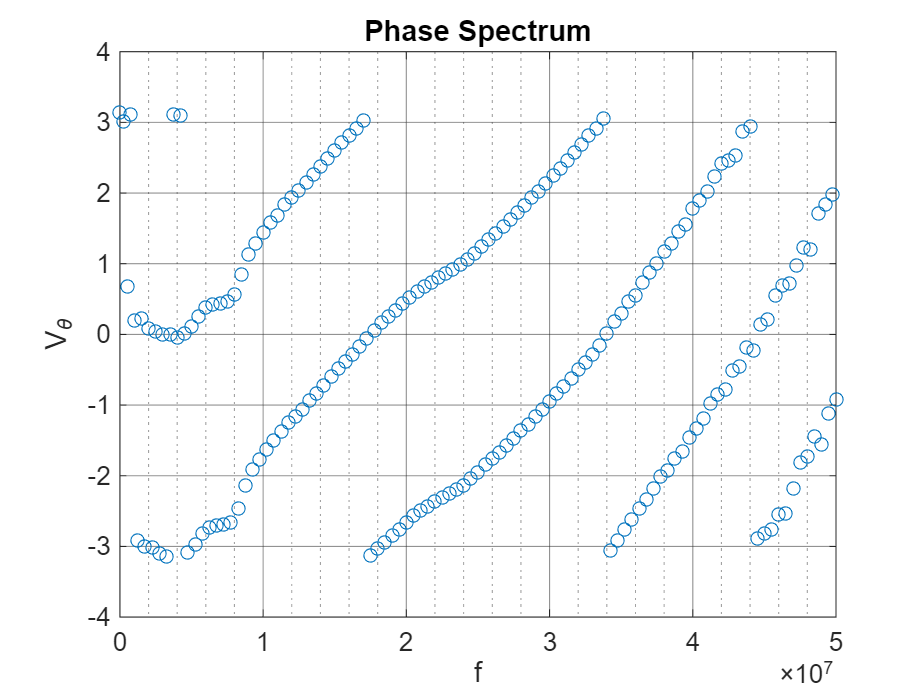

figure2 = figure;
axes2 = axes('Parent',figure2);
hold(axes2,'on');
scatter(f, angle(V))
title('Phase Spectrum');
xlim([0,5e7]);
% ylim([0, 50]);   % optional to resize axis limits
xlabel('f');
ylabel('V_\theta');

box(axes2,'on');
grid(axes2,'on');
hold(axes2,'off');

% Set the remaining axes properties
set(axes2,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')

set(gca,'FontSize',12)

Now we need to find the -3 dB bandwidth of the signal.

btIdx = find(f <= 2500000, 1, 'last'); % exclude the initial low frequencies that have abnormally high amplitudes

Vm = abs(V(btIdx:end));
[max_mag, max_idx] = max(Vm);

db_level = max_mag * 10^(-0.3);

lower_idx = find(Vm(1:max_idx) <= db_level, 1, 'last'); 
upper_idx = find(Vm(max_idx:end) <= db_level, 1, 'first') + max_idx - 1;

lower_frequency = f(lower_idx + btIdx); 
upper_frequency = f(upper_idx + btIdx);

bandwidth = upper_frequency - lower_frequency

bandwidth = 1.7500e+07

Thus, the -3dB bandwidth is around $1.75 * 10^7 Hz$.

## Q2

Find the 90% essential bandwidth of a unit amplitude rectangular pulse with a 1-second duration.

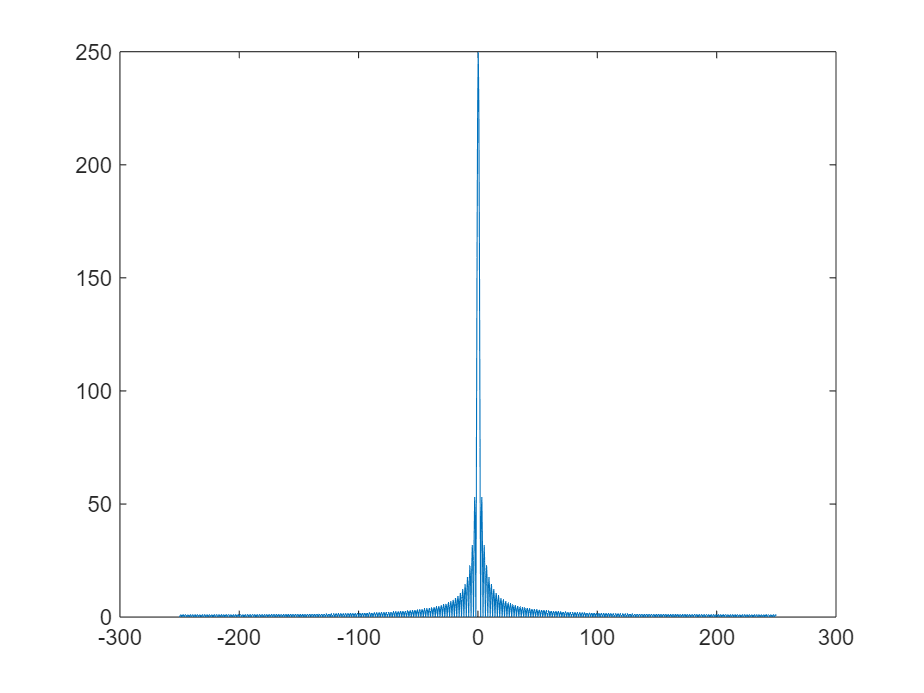

T = 1; % Pulse width
t = linspace(-2*T, 2*T, 1000); % Time vector over a longer interval 

% Define the rectangular pulse 
x = double(abs(t) <= T/2); % Compute the Fourier Transform 
X = fftshift(fft(x)); % Define the frequency vector 
Fs = 1000 / (2*T); % Sampling frequency 
N = length(t); 
f = linspace(-Fs/2, Fs/2, N); % Frequency vector including negative frequencies 

plot(f, abs(X));

total_energy = sum(abs(X(N/2 : end)).^2); % Sum of squared magnitudes 
cumulative_energy = cumsum(abs(X(N/2 : end)).^2); % Cumulative sum of squared magnitudes 
cumulative_energy_normalized = cumulative_energy / total_energy; 

index_90 = find(cumulative_energy_normalized >= 0.9, 1, 'first'); 
frequency_90 = f(N/2 + index_90)

frequency_90 = 1.7518


$$\omega = 2\pi f \\
= 2*\pi*1.7518 \\
= 11.0069 \text{ rad/sec}$$


### Q3

Generate the audio sequence using MATLAB and find its DFT without using MATLAB inbuilt functions and compare your result with MATLAB built-in functions.

% Parameters 
Fs = 4000; % Sample rate (samples per second)
T = 3; % Duration (seconds) 

% Create Time Vector 
t = 0:1/Fs:T-1/Fs; % Generate Audio Signal (Sine Wave) 

audio_signal = 0.5 * sin(2 * pi * 440 * t) + 2 * sin(2 * pi * 880 * t) + 0.25 * sin(2 * pi * 1760 * t);

% Play Audio
% sound(audio_signal, Fs);

% Number of samples
N = length(audio_signal);

X_manual = zeros([1 N]);
omega_0 = 440*pi;
for k = 1:N
    Angle = k * omega_0 * t;
    X_manual(k) = audio_signal * (cos(Angle) + 1i*sin(Angle))';
end

f_manual = (0:N-1) * Fs/N;
magnitude_manual = abs(X_manual)/N;

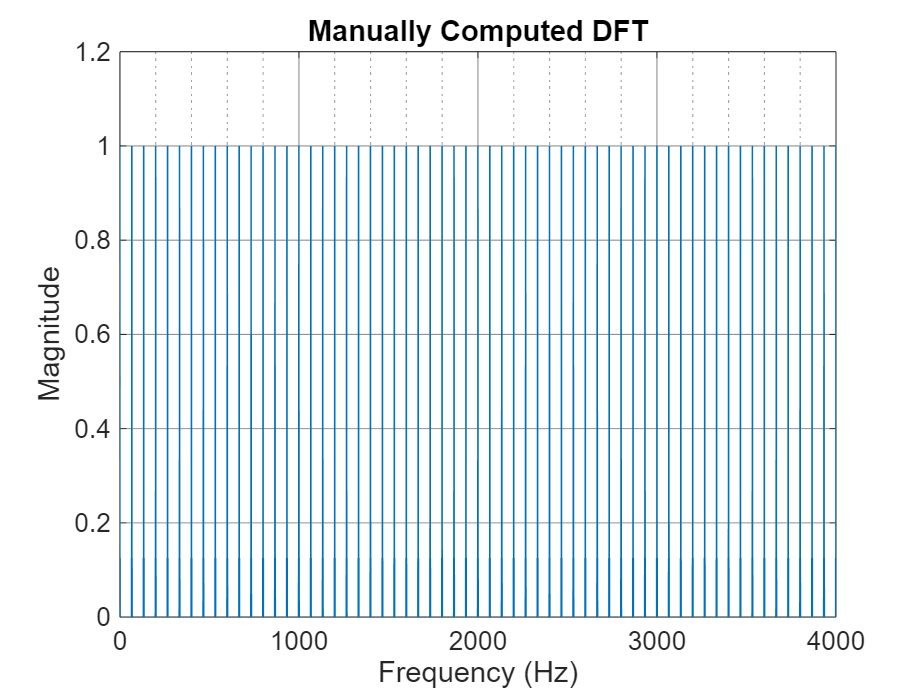

% Plot Comparison
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(f_manual, magnitude_manual);

title('Manually Computed DFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')
set(gca,'FontSize',12)

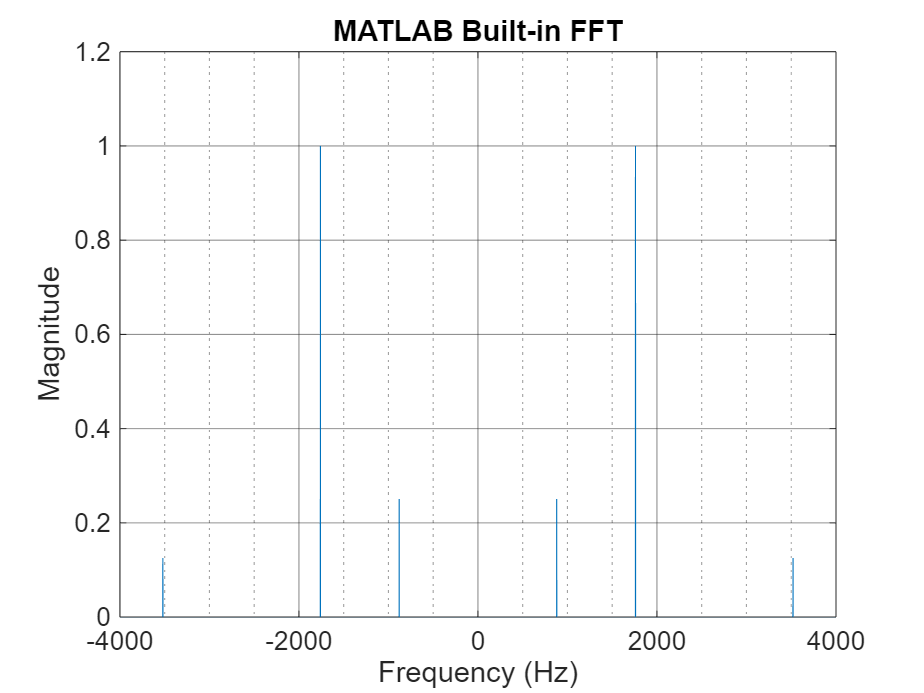

% Compute DFT using MATLAB built-in function
X_builtin = fftshift(fft(audio_signal));

% Magnitude of the built-in DFT
magnitude_builtin = abs(X_builtin)/N;

% Define Frequency Vector
N = length(X_builtin);
f_bultin = (-N/2: (N-1)/2) * (2*Fs / N);

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(f_bultin, magnitude_builtin);

title('MATLAB Built-in FFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')
set(gca,'FontSize',12)

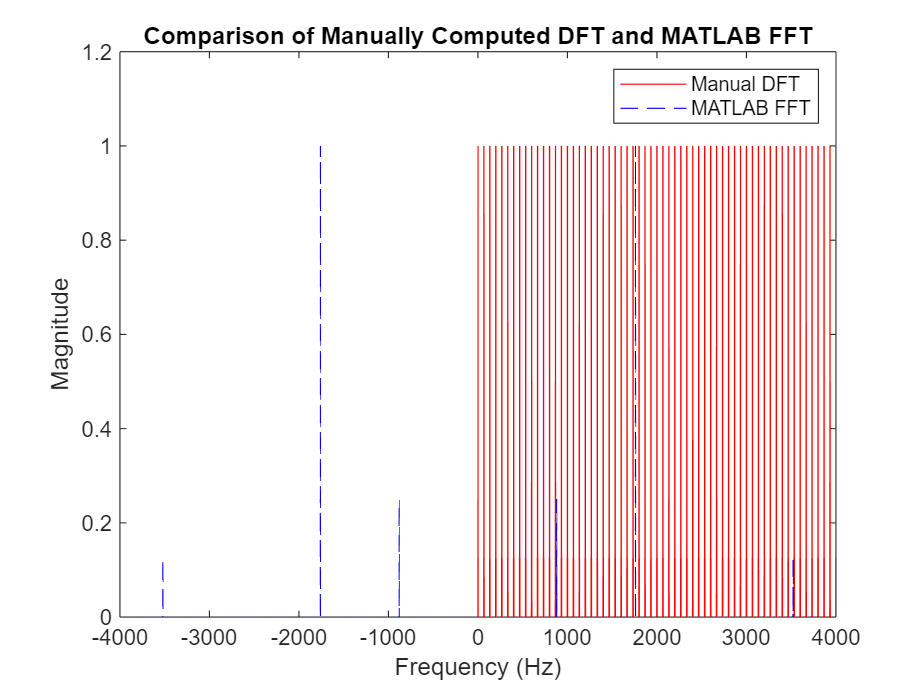

% Display Comparison
figure;
plot(f_manual, magnitude_manual, 'r', f_bultin, magnitude_builtin, 'b--');
title('Comparison of Manually Computed DFT and MATLAB FFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Manual DFT', 'MATLAB FFT');

### Q4

Use the FFT function in MATLAB to compute the Fourier transform of $e^{-2t} u (t)$. Plot the resulting Fourier spectra.

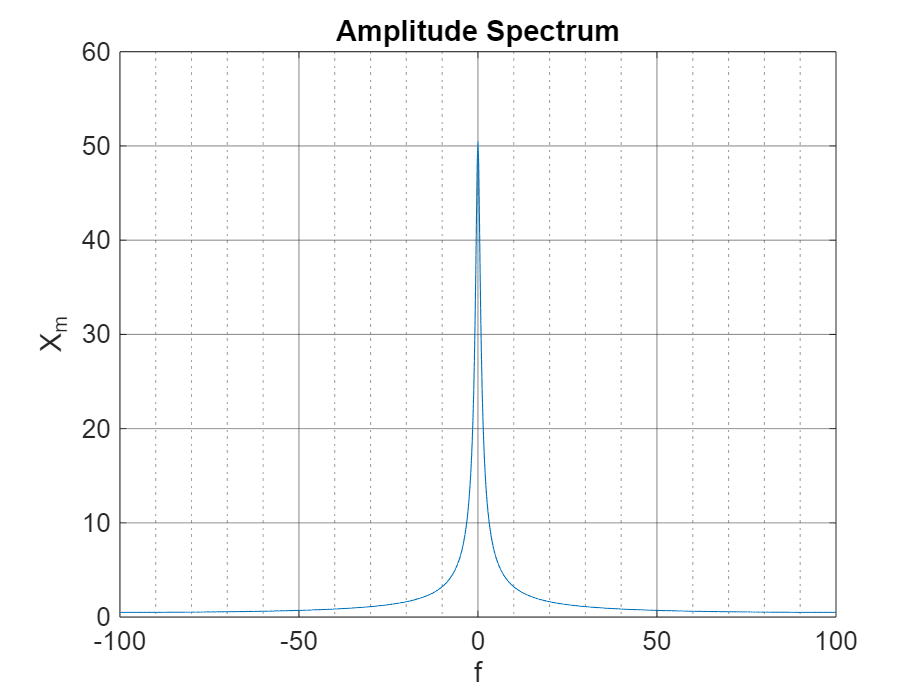

fs = 100;
t = 0:1/fs : 10 - 1/fs;
x = exp(-2 .* t);
X = fftshift(fft(x));

% Define Frequency Vector
N = length(X);
f = (-N/2: (N-1)/2) * (2*fs / N);

% Overlay with Magnitude Spectrum
figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
plot(f, abs(X));

title('Amplitude Spectrum')
xlabel('f');
ylabel('X_m');

% Set the remaining axes properties
box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')
set(gca,'FontSize',12)

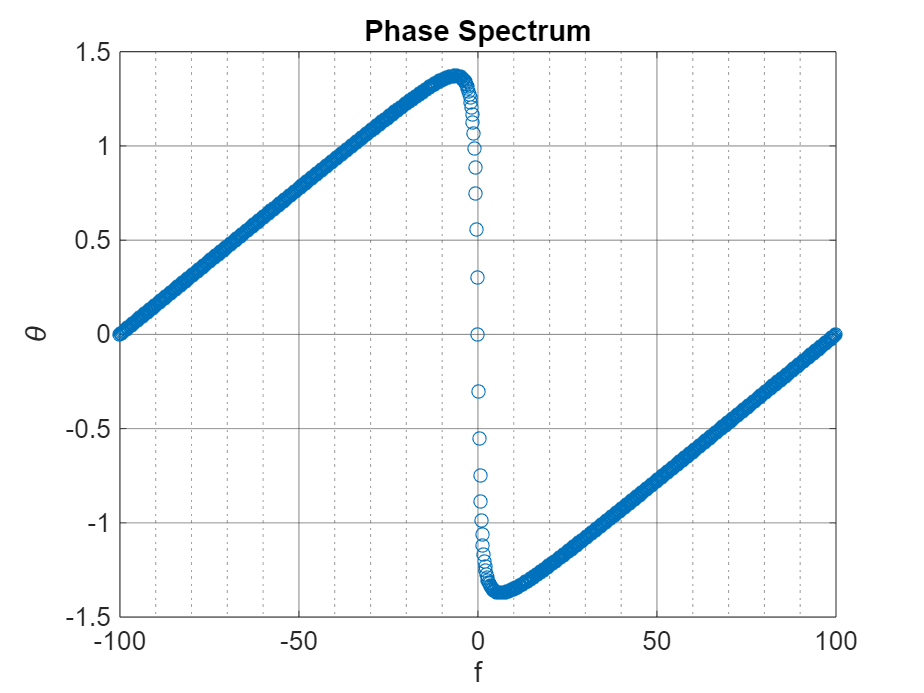

figure1 = figure;
axes1 = axes('Parent',figure1);
hold(axes1,'on');
scatter(f, angle(X));

title('Phase Spectrum')
% xlim([0,10]);
% ylim([0, 0.5]);   % optional to resize axis limits
xlabel('f');
ylabel('\theta');

% Set the remaining axes properties
box(axes1,'on');
grid(axes1,'on');
hold(axes1,'off');
set(axes1,'GridAlpha',0.5,'MinorGridAlpha',0.4,'XMinorGrid','on')
set(gca,'FontSize',12)

### Q5